%clearing the workspace environment
clc
clear
close all

%setting up the camera 

%declaring the webcam to camera
camera = webcam;

%clicking the snapshot using the camera
picture = camera.snapshot;

%clearing the camera
clear camera;

%initilising the pre trained network and then using the transfer learning
%to just modify the network to our own needs
net = alexnet;
inlayer = net.Layers(1)

inlayer =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [227 227 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [227×227×3 single]


expectedSize = inlayer.InputSize

expectedSize =    227   227     3


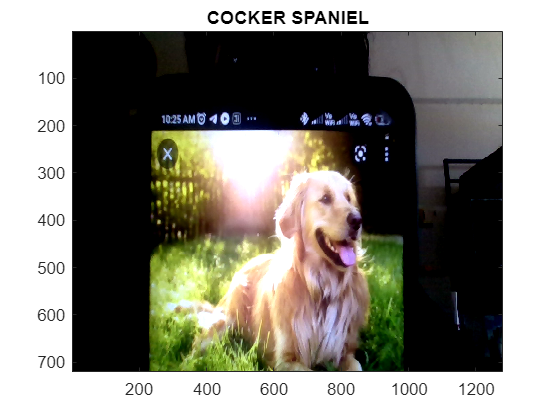


%pre prossing the live data taken from the camera
figure(1);
image(picture);

%resizing the picture so that it can be used for the network
picture = imresize(picture,[227,227]);

%classifying the image taken from the camera
label = classify(net, picture);

%naming the title by the name of classified class 
title(upper(char(label)));